clear

rho0    = 1.21;                 % density of air                        [kg/m^3]
c0      = 343;                  % speed of sound                        [m/s]
s0      = 1.227184630308513E-4; % area of throat                        [m^2]

% specimen -    mic. #2 -   mic. #1 - plane wave tube
% position      x2 -        x1

s       = 0.03;                 % separation distance btw. microphones  [m]
x1      = 0.081;                % position of microphone 1              [m]

rawdata = load('H12.mat');

freq    = rawdata.h12(:,1);
H12     = rawdata.h12(:,2);

% s       = 0.09;                 % separation distance btw. microphones  [m]
% x1      = 0.065;                % position of microphone 1              [m]
% 
% rawdata = load('H126.mat');
% 
% freq    = rawdata.h126(:,1);
% H12     = rawdata.h126(:,2);

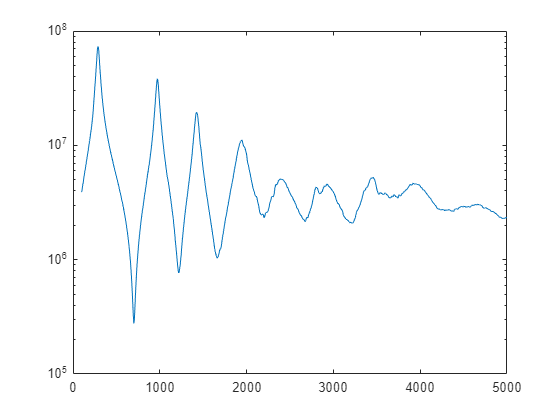

HI      = exp(-1i*2*pi.*freq/c0*s);
HR      = exp(1i*2*pi.*freq/c0*s);

r       = (H12-HI)./(HR-H12).*exp(2i*2*pi.*freq/c0*x1);

Z       = rho0*c0/s0*(1+r)./(1-r);

semilogy(freq, abs(Z));

data = [freq abs(Z) angle(Z)];
save 'Horn acoustic impedance by impedance tube-3cm.txt' data -ascii